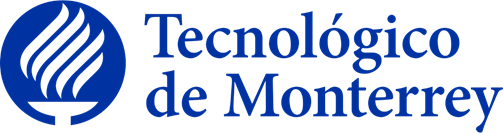

**Instituto Tecnológico y de Estudios Superiores de Monterrey**

TE3002B.502 

**Implementación de robótica Inteligente (Gpo 502)**

Semestre: febrero - junio 2023     

**Alumno:**

		José Angel Ramírez Ramírez   	A01735529

**Profesor: Dr. Alfredo Garcia Suarez.**

Fecha de entrega: 06 de Mayo del 2023

1.** Implementar** el código requerido para generar el seguimiento de los siguientes waypoints (puntos de referencia), ajustando el tiempo de muestreo: **“****sampleTime****”,** vector de tiempo: **“****tVec****”,** pose inicial: **“****initPose****”,** y los waypoints: **“****waypoints****”**

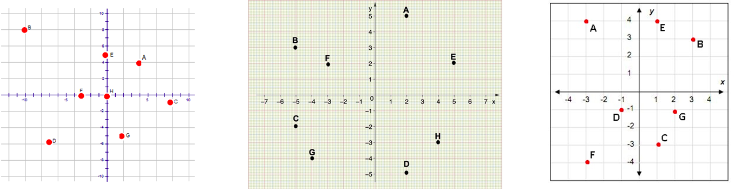

El codigo a usar como referencia es el siguiente, del cual solo se modificara los apartados "Simulation parameters" y "Waypoints"


%% EXAMPLE: Differential drive vehicle following waypoints using the 
% Pure Pursuit algorithm
%
% Copyright 2018-2019 The MathWorks, Inc.

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:120;         % Time array

initPose = [4;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,4; -10,8; 8,-1; -4,-7; 0,5; -3,0; 2,-5; 0,0];
%waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,4; 4,-3 ];
%waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1]; 

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1.0;
controller.MaxAngularVelocity = 20;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
end

Por lo tanto, para poder llevar a la primera trayectoria los parametros de los apartados mencionados anteriormente quedaron modificados de la siguiente manera:

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:80;         % Time array

initPose = [4;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,4; -10,8; 8,-1; -4,-7; 0,5; -3,0; 2,-5; 0,0];

resultado 1: 

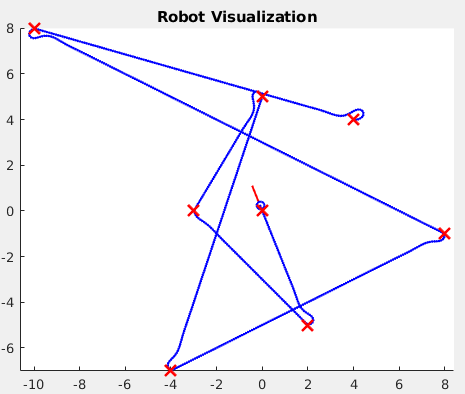

Para la segunda trayectoria quedaron de la siguiente manera

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:50;         % Time array

initPose = [2;5;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [2,5; -5,3; -5,-2; 2,-5; 5,2; -3,2; -4,4; 4,-3 ];

Resultado 2: 

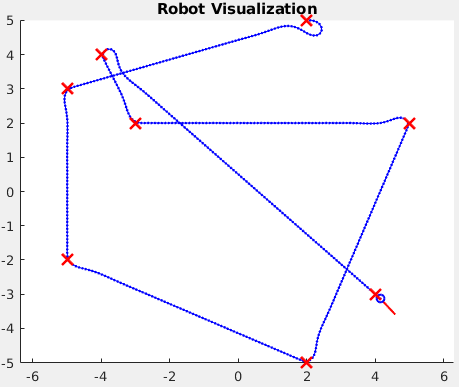

Y por ultimo en la ultima trayectoria fueron los siguientes

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:30.3;         % Time array

initPose = [-3;4;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1]; 

resultado 3:

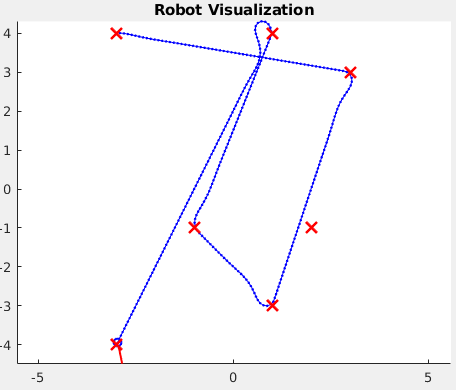

2.** Generar** los waypoints (puntos de referencia) necesarios para obtener las siguientes trayectorias, ajustando el tiempo de muestreo: **“****sampleTime****”,** vector de tiempo: **“****tVec****”,** pose inicial: **“****initPose****”,** y los waypoints: **“****waypoints****”**

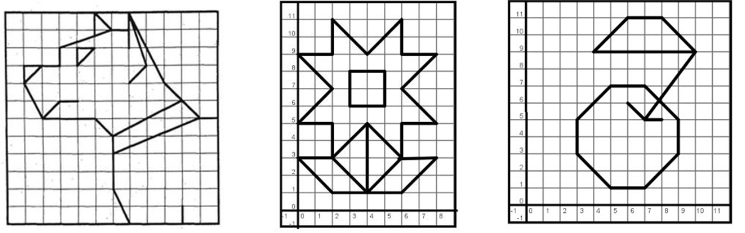

Para la primera figura los parametros de configuracion, con los waypoints quedaron de la siguiente manera:

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:275;         % Time array

initPose = [1;9;pi/4];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [1,9; 3,9; 3,10; 4,9; 5,10; 4,10; 3,10; 6,11; 5,12; 5,10.6;
    6,11; 7,11; 7,8; 8,9; 7,12; 11,6; 12,6; 12,0; 10,0; 10,1; 10,0; 7,0;
    6,2; 6,4; 11,6; 10,7; 6,5; 6,4; 6,5; 5,6; 2,6; 3,7; 4,7; 3,7; 2,6; 1,8;
    2,9; 1,9; 1,8];

%waypoints = [5,1; 4,2; 3,3; 3,4; 3,5; 4,6; 5,7; 6,7; 7,7 ; 8,6; 7,5; 6,6;
%7,5; 8,5;
%7,5; 8,6; 10,9; 9,10; 8,11; 6,11; 5,10; 4,9; 10,9; 8,6; 9,5; 9,3; 8,2; 7,1;
%5,1];


%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 20.0;

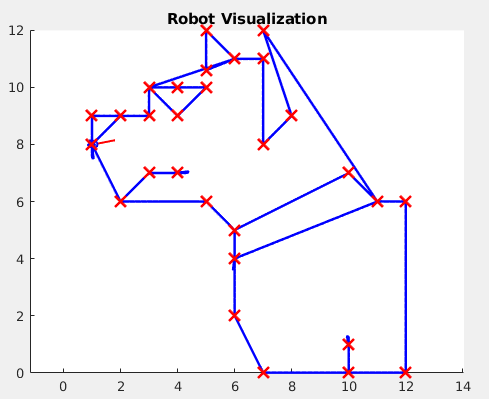

Figura 2

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:231;         % Time array

initPose = [4;1;pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,1; 2,1; 0,3; 2,3; 4,1; 4,5; 2,3; 2,5; 0,5; 2,7; 0,9; 2,9;
            2,11; 4,9; 6,11; 6,9; 8,9; 6,7; 8,5; 6,5; 6,3; 4,5; 4,6; 3,6;
            3,8; 5,8; 5,6; 4,6; 4,1; 6,3; 8,3; 6,1; 4,1;];
 
% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.45;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 20.0;


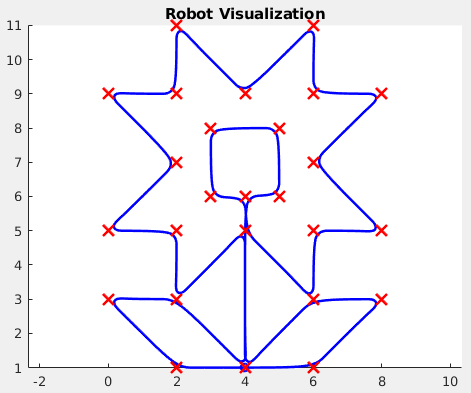

Figura 3:

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:155;         % Time array

initPose = [5;1;3/4*pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints

waypoints = [5,1; 4,2; 3,3; 3,4; 3,5; 4,6; 5,7; 6,7; 7,7 ; 8,6; 7,5; 6,6;
7,5; 8,5;
7,5; 8,6; 10,9; 9,10; 8,11; 6,11; 5,10; 4,9; 10,9; 8,6; 9,5; 9,3; 8,2; 7,1;
5,1];

 

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 0.3;
controller.MaxAngularVelocity = 20.0;